# Sample SLIM (i.e. MDL-SAX) Analysis Demo based upon S&P500, shown for a single month

## Initial Housekeeping

%clear previous outputs
clear all;
close all;
clc;

%Manually setting some color values here, this requires access to the file 'distinguishable_colors.m'
%Available at https://uk.mathworks.com/matlabcentral/fileexchange/29702-generate-maximally-perceptually-distinct-colors
addpath('......');
colors = distinguishable_colors(15);
ColorDark= colors(1,:);
ColorMiddle= colors(2,:);
ColorLight= colors(3,:);

## File Detail Inputs for input time series

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Inputs')

      Inputs


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


S_and_P_500_TSFileName  = "S_and_P_500"

S_and_P_500_TSFileName = "S_and_P_500"


%Add path to folder that contains sample input series
TSFilePath  = "......\" %\" needed at end of path
TSFileExt   = ".xlsx"

TSFilePath = "C:\Users\eoinc\Dropbox\PHD\Motif_Disc_Models\SAX_Matlab\ITISE_Special_Edition_Paper_2022_Reviewer_Changes_Draft_1\Scripts_For_Publication\Input_Series\"

TSFileExt = ".xlsx"

## Add path to SAX Matlab Code Here

%Add path to your folder that contains Keogh Matlab SAX code here
%Available at https://cs.gmu.edu/~jessica/sax.htm
addpath('.....');

## Date Inputs

%Date Inputs
blnUseDateRange = 1

blnUseDateRange =      1


DateFrom = datetime('01-Jan-2008')

DateFrom = datetime
   01-Jan-2008

DateTo = datetime('01-Jan-2010')

DateTo = datetime
   01-Jan-2010

## Create Generalised Variables

%Flags
blnShowOrigPlots = 1;
blnShowNormalisedPlots = 0;

%Create Plot Axes
PltXAxis = "Date";
PltYAxis = "Rate";

## Read In Raw Data (and reduce to date range if needed)

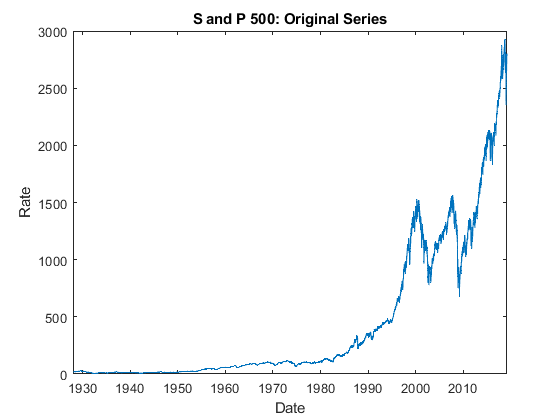

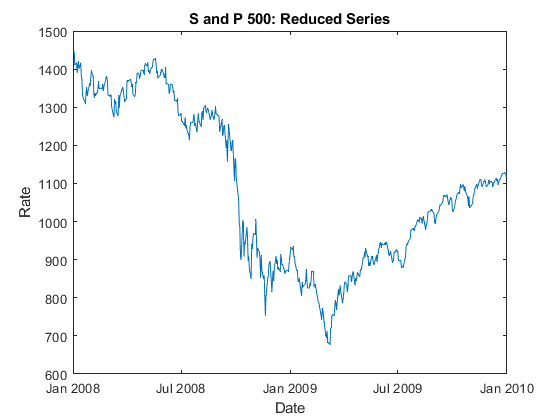

S_And_P500_RawData = InFileToTimeTable(S_and_P_500_TSFileName, TSFilePath, TSFileExt, blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis);


if blnUseDateRange == 1
      Range = timerange(DateFrom,DateTo);
      S_And_P500_Reduced_RawData = S_And_P500_RawData(Range,:);
      TS_Series = S_And_P500_Reduced_RawData.Rate(:,1);
else  
      TS_Series = S_And_P500_RawData.Rate(:,1);             %running full series for now
      S_And_P500_Reduced_RawData = S_And_P500_RawData;      %No need to reduce data to range if looking at full series. This makes sure Examined series values returned in structure are correct
end

## Create SAX String from Matlab Code

data = TS_Series;                   %For Passing Series into SAX function call
[data_len, na] = size(data);        %Get Length of Series for SAX function call
nseg = data_len;                    %Used to control compression levels (on x-axis) i.e how much of original series does each SAX symbol represent
                                    %if nseg = data_len then no compression otherwise length of series (data_len) must be divisible by number of segments (nseg)                                 
alphabet_size = 20;                 %Set size of alphabet i.e. number of distinct symbols used to rtepresent original series

**Note:** setting *nseg = data_len;* means we are not using any copmpression in our SAX representaions here. 

            We willl therefore have a 1:1 match between SAX and raw series elements.

            The code needs to be generalised to allow for 

%Generate SAX string from Keogh Code
[SAXResult, SAXPointer] = timeseries2symbol(data, data_len, nseg, alphabet_size);

% %For MP analysis of SAX string with exising MP code create SAX Result table that includes a date for each symbol.
% %This is currently a 1:1 match as we are not doing any copmpression (on x-axis) i.e how much of original series does each SAX symbol represent, we are setting nseg = data_len; 
SAXResultRawData = S_And_P500_Reduced_RawData;% Create copy of ReducedData table
SAXResultRawData = addvars(SAXResultRawData,transpose(SAXResult)); % Add Column with SAX string values
SAXResultRawData = removevars(SAXResultRawData,"Rate"); % Remove rate column
SAXResultRawData = renamevars(SAXResultRawData,"Var2","Rate"); % Rename SAX column to Rate (Need to use same columnnames as other MP programs)

## Create SAX String From Input File

------------------------------------------------------------------------------------------------------------------------------------

**Note: *****S_and_P_500_SAX_Str_FileName*** is created by a seperate Python Program in order to allow us to use output from the the TSLearn library

The output of this python program is a series of .csv files containging SAX values of the S&P500 over a range of Alphabet sizes.

The individual file used here in this script called "S_and_P_500_SAX_Series" consists of a SAX representation of the S&P500 created by the TSLearn library with an alphabet size of 200

------------------------------------------------------------------------------------------------------------------------------------

S_and_P_500_SAX_Str_FileName  = "S_and_P_500_SAX_Series";
SAXSeriesFileExt   = ".csv";

%Create full filename including path for import
SAXFileName = TSFilePath + S_and_P_500_SAX_Str_FileName + SAXSeriesFileExt; 

fid = fopen(SAXFileName);
a = textscan(fid,'%s',1);
fclose(fid);

%read into initial table and convert into timetable
opts = detectImportOptions(SAXFileName);
opt =  delimitedTextImportOptions;
S_And_P500_RawData = readtable(SAXFileName,'ReadRowNames',false); 
S_And_P500_RawData = table2timetable(S_And_P500_RawData);
FileSAXResultRawData = S_And_P500_RawData;

## Assign SAX String Representations

TS_Keogh_SAX_Series = SAXResult; %i.e SAX series created by Matlab code above
TS_TSLearn_SAX_Series = FileSAXResultRawData.Rate(:,1);
TS_TSLearn_SAX_Series = transpose(TS_TSLearn_SAX_Series); %Transpose to put in same format as other series so treated in same way for remainder of script 

------------------------------------------------------------------------------------------------------------------------------------

**Note: **For experimentation we have now created 2 seperate SAX series based off the S&P500 input series

The first using Matlab code named '***TS_Keogh_SAX_Series***' 

The second using a seperate python script. named '***TS_TSLearn_SAX_Series***'

This is required as the matlab code has a max alphabet size of 20 currently available and we may require higher alphabet size SAX strings for analysis in order to obtain a suitable compression rate.

------------------------------------------------------------------------------------------------------------------------------------

## Display SAX Representations & Raw Series With Dates

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      For comparison raw S&P series along with both SAX series are shown')

      For comparison raw S&P series along with both SAX series are shown


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


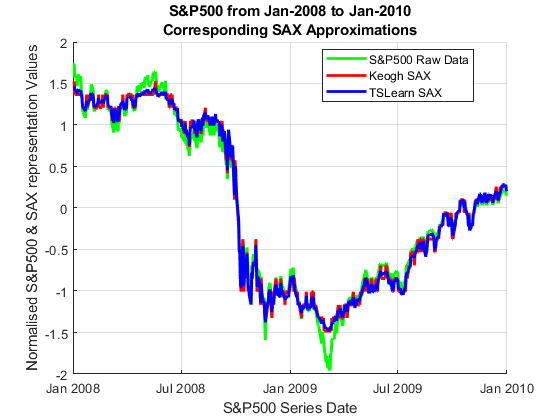


strKeoghSeriesLegend = "Keogh SAX";
strTSLearnSAXSeriesLegend = "TSLearn SAX";
strRawSeriesLegend = "S&P500 Raw Data";
strXLabel = "S&P500 Series Date";
strYLabel = "Normalised S&P500 & SAX representation Values";
%strTitle = "Keogh vs TSLearn SAX Approximation of S&P500";
strTitle = "S&P500 from " + datestr(DateFrom,'mmm-yyyy') + " to " + datestr(DateTo,'mmm-yyyy') + newline + "Corresponding SAX Approximations";

%Just make sure we're usingh the correct S&P500 data
TS_Series_Dates = S_And_P500_Reduced_RawData.Date;
TS_Series_Values = S_And_P500_Reduced_RawData.Rate;
    
%In this case we know num of SAX elements = Num of S&P500 elements so can use same dates for all series
%i.e. we have a 1:1 match between SAX & raw series values

Keogh_Vs_TSLearn_SAX_With_Dates=figure();
hold on
    plot(TS_Series_Dates,normalize(TS_Series_Values),'color','green','DisplayName',strRawSeriesLegend,'LineWidth',2);
    plot(TS_Series_Dates, normalize(TS_Keogh_SAX_Series),'color','red','DisplayName',strKeoghSeriesLegend,'LineWidth',2);
    plot(TS_Series_Dates,normalize(TS_TSLearn_SAX_Series),'color','blue','DisplayName',strTSLearnSAXSeriesLegend,'LineWidth',2);

    %Show legend & Grid
    grid on;
    legend({strRawSeriesLegend,strKeoghSeriesLegend,strTSLearnSAXSeriesLegend})     
    legend('Location','best','color','white');      

    title(strTitle)
    xlabel(strXLabel)
    ylabel(strYLabel)
hold off

## Associate SAX values with dates

%For further analysis create SAX Result table that includes a date for each symbol.
%This is currently a 1:1 match as we are not doing any copmpression (on x-axis) i.e how much of original series does each SAX symbol represent, we are setting nseg = data_len above; 

%Do For Keogh SAX Series First
TS_Keogh_Series_SAX_RawData = S_And_P500_Reduced_RawData;% Create copy of ReducedData table
TS_Keogh_Series_SAX_RawData = addvars(TS_Keogh_Series_SAX_RawData,transpose(TS_Keogh_SAX_Series)); % Add Column with SAX string values from TS_Keogh_Series above
TS_Keogh_Series_SAX_RawData = removevars(TS_Keogh_Series_SAX_RawData,"Rate"); % Remove rate column
TS_Keogh_Series_SAX_RawData = renamevars(TS_Keogh_Series_SAX_RawData,"Var2","Rate"); % Rename SAX column to Rate (Need to use same columnnames as other MP programs)

% %Do For Keogh SAX Series First
TS_TSLearn_Series_SAX_RawData = S_And_P500_Reduced_RawData;% Create copy of ReducedData table
TS_TSLearn_Series_SAX_RawData = addvars(TS_TSLearn_Series_SAX_RawData,transpose(TS_TSLearn_SAX_Series)); % Add Column with SAX string values from TS_TSLearn_Series above
TS_TSLearn_Series_SAX_RawData = removevars(TS_TSLearn_Series_SAX_RawData,"Rate"); % Remove rate column
TS_TSLearn_Series_SAX_RawData = renamevars(TS_TSLearn_Series_SAX_RawData,"Var2","Rate"); % Rename SAX column to Rate (Need to use same columnnames as other MP programs)

## Get MDL SAX Details From SAX Series

------------------------------------------------------------------------------------------------------------------------------------

**Note: **This is the point where we apply MDL principle to the SAX series.

           Application is handled in a seperate function called ***SAX_To_MDL*** that takes the SAX series and raw series as input.

          Output is a table containing MDL-SAX details for further analysis.

------------------------------------------------------------------------------------------------------------------------------------

%Get MDL SAX Table from SAX Series
TS_Keogh_Series_MDLSAX= SAX_To_MDL(TS_Keogh_SAX_Series, TS_Keogh_Series_SAX_RawData);       %Creating MDL_SAX Table (Need same raw data used for creating SAX string here also for getting dates of indexes in original series where comprression occurs
TS_TSLearn_Series_MDLSAX= SAX_To_MDL(TS_TSLearn_SAX_Series, TS_TSLearn_Series_SAX_RawData); %Creating MDL_SAX Table (Need same raw data used for creating SAX string here also for getting dates of indexes in original series where comprression occurs

------------------------------------------------------------------------------------------------------------------------------------

**Note: **To demonstrae compression of SAX string by MDL just focus on a single month (January 2009)

           We will use the Matlab SAX string for this also (i.e. ***TS_Keogh_Series_SAX_RawData***)

------------------------------------------------------------------------------------------------------------------------------------

## Gather single month SAX & MDL-SAX data for Demo Plots

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Display SAX & MDL-SAX values for a single month')

      Display SAX & MDL-SAX values for a single month


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


%Using Jan 2009 Window
SAXDateFrom = datetime('01-Jan-2009')

SAXDateFrom = datetime
   01-Jan-2009

SAXDateTo = datetime('31-Jan-2009')

SAXDateTo = datetime
   31-Jan-2009

Range = timerange(SAXDateFrom,SAXDateTo);

%-------------
%   Standard SAX
%-------------
%TS_Keogh_Series_SAX_RawData is already a timetable so don't need to convert
Reduced_SAX = TS_Keogh_Series_SAX_RawData(Range,:);
Reduced_SAX_Str = Reduced_SAX.Rate;

%-------------
%   MDL SAX
%-------------
Reduced_MDLSAX = table2timetable(TS_Keogh_Series_MDLSAX);
Reduced_MDLSAX = Reduced_MDLSAX(Range,:);
Reduced_MDLSAX_Str = Reduced_MDLSAX.SAXVal;

## Tiled Diag With SAX & MDL String Display

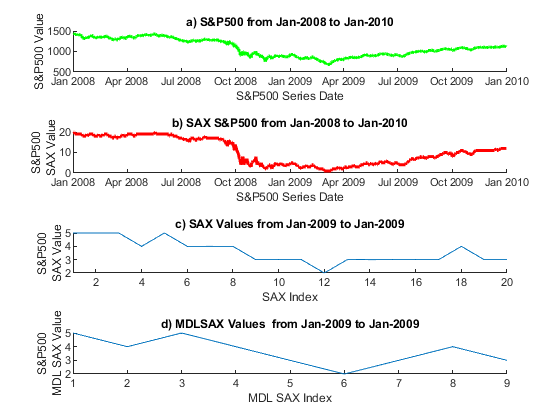

tiledlayout(4,1) % Requires R2019b or later
nexttile
hold on
    strXLabel = "S&P500 Series Date";
    strYLabel = "S&P500 Value";
    strTitle = "a) S&P500 from " + datestr(DateFrom,'mmm-yyyy') + " to " + datestr(DateTo,'mmm-yyyy');

    plot(TS_Series_Dates,TS_Series_Values,'color','green','DisplayName',strRawSeriesLegend,'LineWidth',2);
    
    title(strTitle)
    xlabel(strXLabel)
    ylabel(strYLabel)
hold off  

nexttile
hold on
    strXLabel = "S&P500 Series Date";
    strYLabel = "S&P500" + newline + "   SAX Value";
    strTitle = "b) SAX S&P500 from " + datestr(DateFrom,'mmm-yyyy') + " to " + datestr(DateTo,'mmm-yyyy');
    
    plot(TS_Series_Dates, TS_Keogh_SAX_Series,'color','red','DisplayName',strKeoghSeriesLegend,'LineWidth',2);
    
    title(strTitle)
    xlabel(strXLabel)
    ylabel(strYLabel)
hold off 

nexttile
hold on
    strXLabel = "SAX Index";
    strYLabel = "S&P500" + newline + "SAX Value";
    strTitle = "c) SAX Values from " + datestr(SAXDateFrom,'mmm-yyyy') + " to " + datestr(SAXDateTo,'mmm-yyyy');
    
    plot(Reduced_SAX_Str)
    
    %Set x-axis limits manually
    [Size_Reduced_SAX_Str, NA] = size(Reduced_SAX_Str);%Get size of SAX string (for a single months values)
    xlim([1 Size_Reduced_SAX_Str]) %To remove gap at start of plot
    
    title(strTitle)
    xlabel(strXLabel)
    ylabel(strYLabel)
hold off

nexttile
hold on
    strXLabel = "MDL SAX Index";
    strYLabel = "S&P500" + newline + "MDL SAX Value";
    strTitle = "d) MDLSAX Values  from " + datestr(SAXDateFrom,'mmm-yyyy') + " to " + datestr(SAXDateTo,'mmm-yyyy');
    
    plot(Reduced_MDLSAX_Str)
    
    title(strTitle)
    xlabel(strXLabel)
    ylabel(strYLabel)
hold off

## Function: Read Raw Data

function [RawData] = InFileToTimeTable(InFileName, TSFilePath, TSFileExt, blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis)
    %Input file details for debug of file read (if needed)
    %{
    opts = detectImportOptions(TSFileName);
    preview(TSFileName,opts)
    disp([opts.VariableNames' opts.VariableTypes'])
    %}
    
    %Create full filename including path for import
    TSFileName = TSFilePath + InFileName + TSFileExt; 
        
    %read into initial table and convert into timetable
    opts = detectImportOptions(TSFileName);
    RawData = readtable(TSFileName,opts);    
    RawData = table2timetable(RawData);
    
    %disp('---------------------------------------------------------------------------------')
    %disp('      Raw Data Summary for ' + TSFileName)
    %summary(RawData);
    %disp('---------------------------------------------------------------------------------')
        
    %Display Original Series (As selected by user)
    ShowOriginalSeries(RawData,blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis,InFileName)
end

## Function: Display Original Series

function ShowOriginalSeries(RawData,blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis,TSFileName)

    %Create text for plot titles
    strMainPlotTitleText = TSFileName; %Base off filename for now can change here later
    strMainPlotTitleText = strrep(strMainPlotTitleText,'_',' '); %Remove underscores if any   
    
    %Create Standard Plot Title Variables
    TSOrigSeriesPlotTitle = strMainPlotTitleText + ": Original Series";
    TSOrigSeriesNormalisedPlotTitle = strMainPlotTitleText + ": Normailsed Original Series";
    MatrixProfileSeriesPlotTitle = strMainPlotTitleText + ":  Matrix Profile";
    
    %Create Reduced (Date Range) Plot Title Variables
    TSReducedSeriesPlotTitle = strMainPlotTitleText + ": Reduced Series";
    TSReducedSeriesNormalisedPlotTitle = strMainPlotTitleText + ": Normalised Reduced Series";


    %Plot Original(s) if blnShowOrigPlots is set above
    TS_Orig_Series = RawData.Rate(:,1); 
    TS_Orig_Series_Norm =  normalize(TS_Orig_Series); 
    
    if blnShowOrigPlots == 1
        Orig_Series=figure;
        plot(RawData.Date,TS_Orig_Series)
        title(TSOrigSeriesPlotTitle)
        xlabel(PltXAxis) 
        ylabel(PltYAxis) 
    end   
    if blnShowNormalisedPlots == 1
        Orig_Series_Normalised=figure;
        %Also plot normalised series
        plot(RawData.Date,TS_Orig_Series_Norm)
        title(TSOrigSeriesNormalisedPlotTitle)
        xlabel(PltXAxis) 
        ylabel(PltYAxis) 
    end
    
    %Also handle data range
    if blnUseDateRange == 1        
        
        %First reduce the data according to date range specified above
        Range = timerange(DateFrom,DateTo);
        ReducedData = RawData(Range,:);
        TS_Reduced_Series = ReducedData.Rate(:,1);
        TS_Reduced_Series_Norm =  normalize(TS_Reduced_Series); 
        
        if blnShowOrigPlots == 1
            %Then plot
            Reduced_Series=figure;
            plot(ReducedData.Date,TS_Reduced_Series)
            title(TSReducedSeriesPlotTitle)
            xlabel(PltXAxis) 
            ylabel(PltYAxis)
        end
        if blnShowNormalisedPlots == 1
            %Also plot normalised series
            Reduced_Series_Normalised=figure;
            plot(ReducedData.Date,TS_Reduced_Series_Norm)
            title(TSReducedSeriesNormalisedPlotTitle)
            xlabel(PltXAxis) 
            ylabel(PltYAxis)
        end
            
    end
end

## Function: Apply MDL to SAX String

function [SAXMDL] = SAX_To_MDL(InstrSAX, RawData)
    %{
    Function to apply Minimum Description Length Principal to an input string of SAX symbols

    Output is a table containing 
        SAXVal:
        SymJoinNum: number of combined symbols (if any: No cpompression =1)
        Index: Start index in original series (i.e. Where SAXVal is located)
    %}
    %disp('-- Applying MDL to SAX String --')
    %InstrSAX
    
    [na,intSAXStrLength] = size(InstrSAX);
    SAXMDL = table;
    
    SymJoinNum = 1;     %Used to store number of combined symbols (if any: No compression =1)
    SymIndexNum = 1;    %Used to store value of start index in original series
      
    for i=2:intSAXStrLength
          %srtDisp = "-- Applying MDL to Index: " + i + " --"          
          preval = InstrSAX(i-1);
          curval = InstrSAX(i);
          valdiff = curval - preval;
          
          if curval == preval
              SymJoinNum = SymJoinNum + 1;      
              %Need to ensure final values are also saved when reaching end of InstrSAX & MDL is taking place
              if i == intSAXStrLength
                  strSavingVals = "**** SAXVal: " + preval + " SymJoinNum: " + SymJoinNum + " Start Index: " + SymIndexNum + " ****";              
                  tbl_Line = table(preval,SymJoinNum,SymIndexNum);
                  SAXMDL = [SAXMDL; tbl_Line];
              end
          else
              strSavingVals = "**** SAXVal: " + preval + " SymJoinNum: " + SymJoinNum + " Start Index: " + SymIndexNum + " ****";                           
              tbl_Line = table(preval,SymJoinNum,SymIndexNum);
              SAXMDL = [SAXMDL; tbl_Line];
              
              SymJoinNum = 1;    % reset join num
              SymIndexNum = i;   %Store current index num for record of start index of next symbol join (if any)
          end          
    end
    SAXMDL.Properties.VariableNames = {'SAXVal' 'SymJoinNum' 'RawSeriesIndex'};
  
    %Add Extra column containing difference between adjacent SAX symbols
    MDLSAXStr = SAXMDL.SAXVal; %Get newly calculated MDL SAX Values to be used in call to Get_SAX_Diff_String 
    MDLSAXStr = transpose(MDLSAXStr);
    %Already have a function for calculating difference between adjacent SAX symbols so re-use
    MDL_SAX_Diff_String = Get_SAX_Diff_String(MDLSAXStr);
    
    SAXValDiff = MDL_SAX_Diff_String.SAXValDiff; %Get Difference in MDL SAX Values to be added to SAXMDL table
    SAXMDL = addvars(SAXMDL,SAXValDiff,'After','SAXVal');% Add MDL SAX Diifference Values to SAXMDL table
    
    %Add Extra column containing Date of first occurance of combined SAX symbols (i.e. date of SymIndexNum)
    %First need to get a list of dates
    for i=1:height(SAXMDL)
        OrigSeriesIndex = SAXMDL.RawSeriesIndex(i);
        OrigSeriesDate = RawData.Date(OrigSeriesIndex);
        IndexDate(i) = OrigSeriesDate;    
    end

    SAXMDL = addvars(SAXMDL,transpose(IndexDate),'After','RawSeriesIndex');% Add MDL SAX Diifference Values to SAXMDL table
    SAXMDL = renamevars(SAXMDL,"Var5","RawSeriesDate"); % Rename column to IndexDate
    
     %Add Extra column containing index of SAX symbols (i.e. position of SAX symbol in overal series)
     %Not strictly needed at the moment 0but useful for comparison and may be used in the future
    SAXSeriesIndex = 1:height(SAXMDL);
    SAXMDL = addvars(SAXMDL,transpose(SAXSeriesIndex),'Before','SAXVal');% Add MDL SAX Series index to SAXMDL table
    SAXMDL = renamevars(SAXMDL,"Var1","SAXSeriesIndex"); % Rename column to SAXSeriesIndex
end

## Function: Get Difference between SAX Symbols

function [SAXDiffResult] = Get_SAX_Diff_String(InstrSAX)   
    [na,intSAXStrLength] = size(InstrSAX);     %Calculating size of SAX string
    SAXDiffResult = table;    
    
    %Place first SAX value in table with a default difference of 0
    tbl_Line = table(InstrSAX(1,1),0);
    tbl_Line.Properties.VariableNames = {'SAXVal' 'SAXValDiff'};
    SAXDiffResult = [SAXDiffResult; tbl_Line];
     
    for i=2:intSAXStrLength       
      preval = InstrSAX(i-1);
      curval = InstrSAX(i);
      valdiff = curval - preval;
     
      tbl_Line = table(curval,valdiff);
      tbl_Line.Properties.VariableNames = {'SAXVal' 'SAXValDiff'};
      SAXDiffResult = [SAXDiffResult; tbl_Line];
     
    end
    SAXDiffResult.Properties.VariableNames = {'SAXVal' 'SAXValDiff'};
end